%Using function at end combine all group node strengths 
group_snc_control_pff = groupNodeStrength(snc_control_pff);
group_snc_injected_pff = groupNodeStrength(snc_injected_pff);
group_snc_control_asyn = groupNodeStrength(snc_control_asyn);
group_snc_injected_asyn = groupNodeStrength(snc_injected_pff);
group_vta_control_pff = groupNodeStrength(vta_control_pff);
group_vta_injected_pff = groupNodeStrength(vta_injected_pff);
group_vta_control_asyn = groupNodeStrength(vta_control_asyn);
group_vta_injected_asyn = groupNodeStrength(vta_injected_asyn);

% To set the largest edge you'll want to check the bin of each group:
% max_data_snc_pff = max([group_snc_control_pff, group_snc_injected_pff])
% max_data_snc_asyn = max([group_snc_control_asyn, group_snc_injected_asyn])
% max_data_vta_pff = max([group_vta_control_pff, group_vta_injected_pff])
% max_data_vta_asyn = max([group_vta_control_asyn, group_vta_injected_asyn])
% edges = [0:0.1:max_data+0.1]

### Normalized Node Strength Stats  


[h1,p1,ci1,stats1] = ttest2(group_snc_control_pff, group_snc_injected_pff);
[h2,p2,ci2,stats2] = ttest2(group_vta_control_pff, group_vta_injected_pff);
[h3,p3,ci3,stats3] = ttest2(group_snc_control_asyn, group_snc_injected_asyn);
[h4,p4,ci4,stats4] = ttest2(group_vta_control_asyn, group_vta_injected_asyn);

disp('SNC Control versus Injected PFF:')

SNC Control versus Injected PFF:


disp(['Test Statistic: ', num2str(stats1.tstat)]);

Test Statistic: -2.5887


disp(['P-value: ', num2str(p1)]);

P-value: 0.01369


disp('Confidence Interval:');

Confidence Interval:


disp(ci1);

   -0.4559   -0.0556




disp('VTA Control versus Injected PFF:')

VTA Control versus Injected PFF:


disp(['Test Statistic: ', num2str(stats2.tstat)]);

Test Statistic: 0.044407


disp(['P-value: ', num2str(p2)]);

P-value: 0.96472


disp('Confidence Interval:');

Confidence Interval:


disp(ci2);

   -0.1147    0.1199




disp('SNC Control Asyn versus Injected Asyn:')

SNC Control Asyn versus Injected Asyn:


disp(['Test Statistic: ', num2str(stats3.tstat)]);

Test Statistic: -4.1264


disp(['P-value: ', num2str(p3)]);

P-value: 0.00014932


disp('Confidence Interval:');

Confidence Interval:


disp(ci3);

   -0.4540   -0.1564




disp('VTA Control Asyn versus Injected Asyn:')

VTA Control Asyn versus Injected Asyn:


disp(['Test Statistic: ', num2str(stats4.tstat)]);

Test Statistic: -1.7998


disp(['P-value: ', num2str(p4)]);

P-value: 0.075447


disp('Confidence Interval:');

Confidence Interval:


disp(ci4);

   -0.1550    0.0077



## Normalized Node Frequency Plots 

Saves as svg

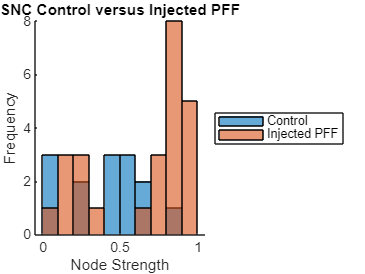

% Define the directory path
output_directory = 'F:\Data\Slice Video Processing\figure_outputs_matlab\graphs';

% Create the directory if it doesn't exist
if ~exist(output_directory, 'dir')
    mkdir(output_directory);
end

edges = [0:0.1:1];

% Histogram for SNC Control versus Injected PFF
figure;
histogram(group_snc_control_pff,edges);
hold on;
histogram(group_snc_injected_pff,edges);
title('SNC Control versus Injected PFF', '');
legend('Control', 'Injected PFF', 'Location', 'eastoutside');
xlabel('Node Strength');
ylabel('Frequency')
box off;
saveas(gcf, fullfile(output_directory, 'SNC_Control_vs_Injected_PFF.svg'));

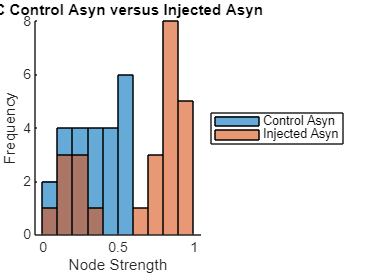

% Histogram for SNC Control Asyn versus Injected Asyn

figure;
histogram(group_snc_control_asyn ,edges);
hold on;
histogram(group_snc_injected_asyn,edges);
title('SNC Control Asyn versus Injected Asyn');
legend('Control Asyn', 'Injected Asyn',  'Location', 'eastoutside');
xlabel('Node Strength');
ylabel('Frequency')
box off;
saveas(gcf, fullfile(output_directory, 'SNC_Control_Asyn_vs_Injected_Asyn.svg'));

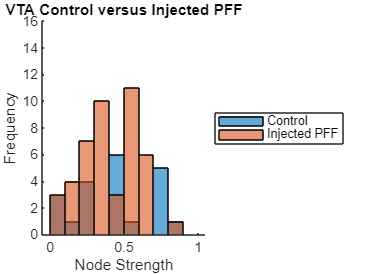

% Histogram for VTA Control versus Injected PFF
figure;
histogram(group_vta_control_pff,edges);
hold on;
histogram(group_vta_injected_pff,edges);
title('VTA Control versus Injected PFF');
legend('Control', 'Injected PFF', 'Location', 'eastoutside');
xlabel('Node Strength');
ylabel('Frequency')
ylim([0 16]);
yticks(0:2:16);
box off;
saveas(gcf, fullfile(output_directory, 'VTA_Control_vs_Injected_PFF.svg'));

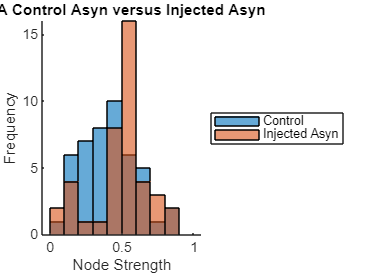

% Histogram for VTA Control Asyn versus Injected Asyn
figure;
histogram(group_vta_control_asyn ,edges);
hold on;
histogram(group_vta_injected_asyn,edges);
title('VTA Control Asyn versus Injected Asyn');
legend('Control', 'Injected Asyn',  'Location', 'eastoutside');
xlabel('Node Strength');
ylabel('Frequency')
box off;
saveas(gcf, fullfile(output_directory, 'VTA_Control_Asyn_vs_Injected_Asyn.svg'));

## Pie Graphs comparing injected versus uninjeced distributions above the mean within the same region 

%Set mean of each group 
mean_snc_pff = mean([group_snc_control_pff, group_snc_injected_pff])

mean_snc_pff = 0.5282

mean_snc_asyn = mean([group_snc_control_asyn, group_snc_injected_asyn])

mean_snc_asyn = 0.4705

mean_vta_pff = mean([group_vta_control_pff, group_vta_injected_pff])

mean_vta_pff = 0.3969

mean_vta_asyn = mean([group_vta_control_asyn, group_vta_injected_asyn])

mean_vta_asyn = 0.4409

 Plots 

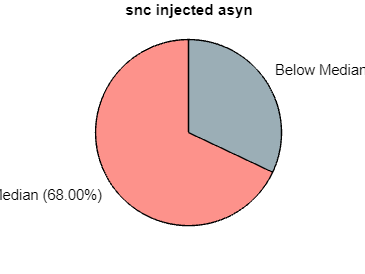

output_directory = 'F:\Data\Slice Video Processing\figure_outputs_matlab\graphs';
if ~exist(output_directory, 'dir')
    mkdir(output_directory);
end

% Find indices of elements above the mean 
above_mean_snc_injected_asyn = find([group_snc_injected_asyn] > mean_snc_asyn);
below_mean_snc_injected_asyn = find([group_snc_injected_asyn] < mean_snc_asyn);

freq_above_mean_snc_injected_asyn = length(above_mean_snc_injected_asyn);
freq_below_mean_snc_injected_asyn = length(below_mean_snc_injected_asyn);

% Calculate percentages
total_count = freq_above_mean_snc_injected_asyn + freq_below_mean_snc_injected_asyn;
percentage_above_mean = (freq_above_mean_snc_injected_asyn / total_count) * 100;
percentage_below_mean = (freq_below_mean_snc_injected_asyn / total_count) * 100;

labels = {sprintf('Above Median (%.2f%%)', percentage_above_mean), sprintf('Below Median (%.2f%%)', percentage_below_mean)};

colorO = [0.996 0.576 0.549; 0.611 0.686 0.717];

counts9 = [freq_above_mean_snc_injected_asyn, freq_below_mean_snc_injected_asyn];

figure;
pie(counts9, labels);
colormap(colorO);
saveas(gcf, fullfile(output_directory, 'Pie_SNC_inj_asyn_mean_injected_uninjected.svg'));

title('snc injected asyn');

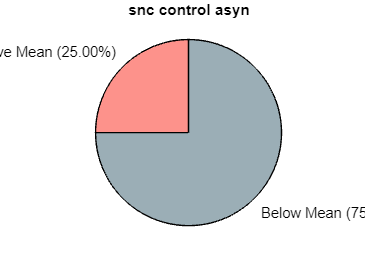


% Find indices of elements above the mean 
above_mean_snc_control_asyn = find([group_snc_control_asyn] > mean_snc_asyn);
below_mean_snc_control_asyn = find([group_snc_control_asyn] < mean_snc_asyn);

freq_above_mean_snc_control_asyn = length(above_mean_snc_control_asyn);
freq_below_mean_snc_control_asyn = length(below_mean_snc_control_asyn);

total_snc_control_asyn = freq_above_mean_snc_control_asyn + freq_below_mean_snc_control_asyn;
percentage_above_mean_snc_control_asyn = (freq_above_mean_snc_control_asyn / total_snc_control_asyn) * 100;
percentage_below_mean_snc_control_asyn = (freq_below_mean_snc_control_asyn / total_snc_control_asyn) * 100;

labels = {sprintf('Above Mean (%.2f%%)', percentage_above_mean_snc_control_asyn), sprintf('Below Mean (%.2f%%)', percentage_below_mean_snc_control_asyn)};

colorB = [0.264 0.505 0.643; 0.611 0.686 0.717];

counts10 = [freq_above_mean_snc_control_asyn, freq_below_mean_snc_control_asyn];

figure;
pie(counts10, labels);
colormap(colorO);
title('snc control asyn');
saveas(gcf, fullfile(output_directory, 'Pie_SNC_control_asyn_mean_injected_uninjected.svg'));

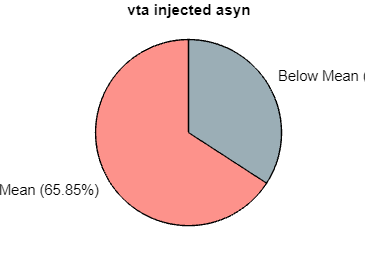

% Similar modifications for other pie charts...

% Find indices of elements above the median 
above_mean_vta_injected_asyn = find([group_vta_injected_asyn] > mean_vta_asyn);
below_mean_vta_injected_asyn = find([group_vta_injected_asyn] < mean_vta_asyn);

freq_above_mean_vta_injected_asyn = length(above_mean_vta_injected_asyn);
freq_below_mean_vta_injected_asyn = length(below_mean_vta_injected_asyn);

total_vta_injected_asyn = freq_above_mean_vta_injected_asyn + freq_below_mean_vta_injected_asyn;
percentage_above_mean_vta_injected_asyn = (freq_above_mean_vta_injected_asyn / total_vta_injected_asyn) * 100;
percentage_below_mean_vta_injected_asyn = (freq_below_mean_vta_injected_asyn / total_vta_injected_asyn) * 100;

labels = {sprintf('Above Mean (%.2f%%)', percentage_above_mean_vta_injected_asyn), sprintf('Below Mean (%.2f%%)', percentage_below_mean_vta_injected_asyn)};

counts11 = [freq_above_mean_vta_injected_asyn, freq_below_mean_vta_injected_asyn];

figure;
pie(counts11, labels);
colormap(colorO);

title('vta injected asyn');
saveas(gcf, fullfile(output_directory, 'Pie_VTA_inj_asyn_mean_injected_uninjected.svg'));

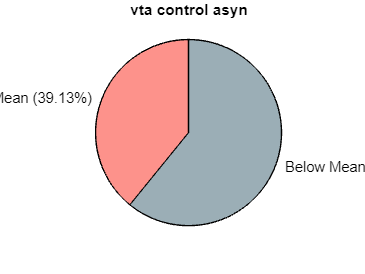

% Find indices of elements above the mean 
above_mean_vta_control_asyn = find([group_vta_control_asyn] > mean_vta_asyn);
below_mean_vta_control_asyn = find([group_vta_control_asyn] < mean_vta_asyn);

freq_above_mean_vta_control_asyn = length(above_mean_vta_control_asyn);
freq_below_mean_vta_control_asyn = length(below_mean_vta_control_asyn);

total_vta_control_asyn = freq_above_mean_vta_control_asyn + freq_below_mean_vta_control_asyn;
percentage_above_mean_vta_control_asyn = (freq_above_mean_vta_control_asyn / total_vta_control_asyn) * 100;
percentage_below_mean_vta_control_asyn = (freq_below_mean_vta_control_asyn / total_vta_control_asyn) * 100;

labels = {sprintf('Above Mean (%.2f%%)', percentage_above_mean_vta_control_asyn), sprintf('Below Mean (%.2f%%)', percentage_below_mean_vta_control_asyn)};

colorB = [0.264 0.505 0.643; 0.611 0.686 0.717];

counts12 = [freq_above_mean_vta_control_asyn, freq_below_mean_vta_control_asyn];

figure;
pie(counts12, labels);
colormap(colorO);

title('vta control asyn');
saveas(gcf, fullfile(output_directory, 'Pie_VTA_control_asyn_mean_injected_uninjected.svg'));

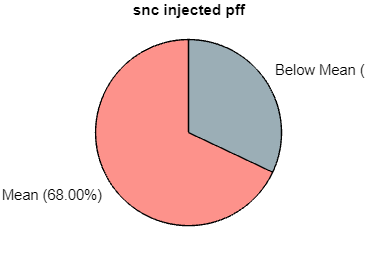


% Find indices of elements above the mean 
above_mean_snc_injected_pff = find([group_snc_injected_pff] > mean_snc_pff);
below_mean_snc_injected_pff = find([group_snc_injected_pff] < mean_snc_pff);

freq_above_mean_snc_injected_pff = length(above_mean_snc_injected_pff);
freq_below_mean_snc_injected_pff = length(below_mean_snc_injected_pff);

total_snc_injected_pff = freq_above_mean_snc_injected_pff + freq_below_mean_snc_injected_pff;
percentage_above_mean_snc_injected_pff = (freq_above_mean_snc_injected_pff / total_snc_injected_pff) * 100;
percentage_below_mean_snc_injected_pff = (freq_below_mean_snc_injected_pff / total_snc_injected_pff) * 100;

labels = {sprintf('Above Mean (%.2f%%)', percentage_above_mean_snc_injected_pff), sprintf('Below Mean (%.2f%%)', percentage_below_mean_snc_injected_pff)};

colorO = [0.996 0.576 0.549; 0.611 0.686 0.717];

counts13 = [freq_above_mean_snc_injected_pff, freq_below_mean_snc_injected_pff];

figure;
pie(counts13, labels);
colormap(colorO);

title('snc injected pff');
saveas(gcf, fullfile(output_directory, 'Pie_SNc_inj_pff_mean_injected_uninjected.svg'));

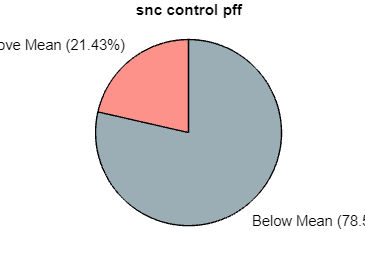

% Find indices of elements above the mean 
above_mean_snc_control_pff = find([group_snc_control_pff] > mean_snc_pff);
below_mean_snc_control_pff = find([group_snc_control_pff] < mean_snc_pff);

freq_above_mean_snc_control_pff = length(above_mean_snc_control_pff);
freq_below_mean_snc_control_pff = length(below_mean_snc_control_pff);

total_snc_control_pff = freq_above_mean_snc_control_pff + freq_below_mean_snc_control_pff;
percentage_above_mean_snc_control_pff = (freq_above_mean_snc_control_pff / total_snc_control_pff) * 100;
percentage_below_mean_snc_control_pff = (freq_below_mean_snc_control_pff / total_snc_control_pff) * 100;

labels = {sprintf('Above Mean (%.2f%%)', percentage_above_mean_snc_control_pff), sprintf('Below Mean (%.2f%%)', percentage_below_mean_snc_control_pff)};

colorB = [0.264 0.505 0.643; 0.611 0.686 0.717];

counts14 = [freq_above_mean_snc_control_pff, freq_below_mean_snc_control_pff];

figure;
pie(counts14, labels);
colormap(colorO);

title('snc control pff');
saveas(gcf, fullfile(output_directory, 'Pie_SNc_control_pff_mean_injected_uninjected.svg'));

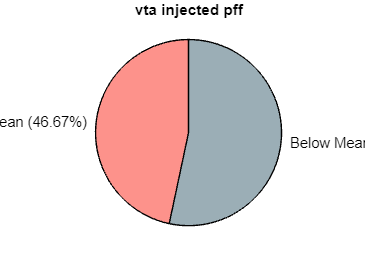

% Find indices of elements above the mean 
above_mean_vta_injected_pff = find([group_vta_injected_pff] > mean_vta_pff);
below_mean_vta_injected_pff = find([group_vta_injected_pff] < mean_vta_pff);

freq_above_mean_vta_injected_pff = length(above_mean_vta_injected_pff);
freq_below_mean_vta_injected_pff = length(below_mean_vta_injected_pff);

total_vta_injected_pff = freq_above_mean_vta_injected_pff + freq_below_mean_vta_injected_pff;
percentage_above_mean_vta_injected_pff = (freq_above_mean_vta_injected_pff / total_vta_injected_pff) * 100;
percentage_below_mean_vta_injected_pff = (freq_below_mean_vta_injected_pff / total_vta_injected_pff) * 100;

labels = {sprintf('Above Mean (%.2f%%)', percentage_above_mean_vta_injected_pff), sprintf('Below Mean (%.2f%%)', percentage_below_mean_vta_injected_pff)};

colorO = [0.996 0.576 0.549; 0.611 0.686 0.717];

counts15 = [freq_above_mean_vta_injected_pff, freq_below_mean_vta_injected_pff];

figure;
pie(counts15, labels);
colormap(colorO);

title('vta injected pff');
saveas(gcf, fullfile(output_directory, 'Pie_VTA_inj_pff_mean_injected_uninjected.svg'));

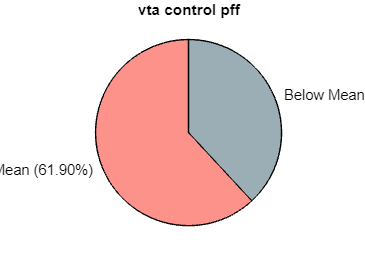

% Find indices of elements above the mean 
above_mean_vta_control_pff = find([group_vta_control_pff] > mean_vta_pff);
below_mean_vta_control_pff = find([group_vta_control_pff] < mean_vta_pff);

freq_above_mean_vta_control_pff = length(above_mean_vta_control_pff);
freq_below_mean_vta_control_pff = length(below_mean_vta_control_pff);

total_vta_control_pff = freq_above_mean_vta_control_pff + freq_below_mean_vta_control_pff;
percentage_above_mean_vta_control_pff = (freq_above_mean_vta_control_pff / total_vta_control_pff) * 100;
percentage_below_mean_vta_control_pff = (freq_below_mean_vta_control_pff / total_vta_control_pff) * 100;

labels = {sprintf('Above Mean (%.2f%%)', percentage_above_mean_vta_control_pff), sprintf('Below Mean (%.2f%%)', percentage_below_mean_vta_control_pff)};
colorB = [0.264 0.505 0.643; 0.611 0.686 0.717];
counts16 = [freq_above_mean_vta_control_pff, freq_below_mean_vta_control_pff];
figure;
pie(counts16, labels);
colormap(colorO);
title('vta control pff');
saveas(gcf, fullfile(output_directory, 'Pie_VTA_control_pff_mean_injected_uninjected.svg'));

Normalized Node Strength - Regions 

**Normalized Node Strength Graphs and  Regions**

% output_directory = 'F:\Data\Slice Video Processing\figure_outputs_matlab\graphs';
% if ~exist(output_directory, 'dir')
%     mkdir(output_directory);
% end
% 
% edges = [0:0.1:1]

edges =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


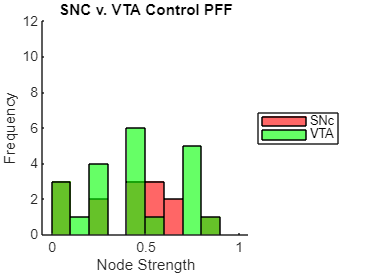

% 
% figure;
% histogram(group_snc_control_pff, edges, 'FaceColor', 'red');
% hold on;
% histogram(group_vta_control_pff, edges, 'FaceColor', 'green');
% title('SNC v. VTA Control PFF', '');
% legend('SNc', 'VTA', 'Location', 'eastoutside');
% xlabel('Node Strength');
% ylabel('Frequency')
% ylim([0 12]);
% yticks(0:2:12);
% box off;
% saveas(gcf, fullfile(output_directory, 'Region SNC Control versus VTA Control PFF.svg'));

% 
% [h1,p1,ci1,stats1] = ttest2(group_vta_control_pff, group_snc_control_pff);
% disp('VTA Control versus SNc Control PFF:')

VTA Control versus SNc Control PFF:


% disp(['Test Statistic: ', num2str(stats1.tstat)]);

Test Statistic: 0.38596


% disp(['P-value: ', num2str(p1)]);

P-value: 0.702


% disp('Confidence Interval:');

Confidence Interval:


% disp(ci1);

   -0.1467    0.2154



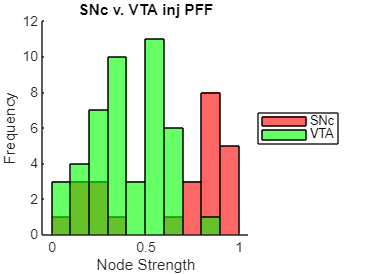

% 
% figure;
% histogram(group_snc_injected_pff,edges, 'FaceColor', 'red');
% hold on;
% histogram(group_vta_injected_pff,edges, 'FaceColor', 'green');
% title('SNc v. VTA inj PFF');
% legend('SNc', 'VTA', 'Location', 'eastoutside');
% xlabel('Node Strength');
% ylabel('Frequency')
% ylim([0 12]);
% yticks(0:2:12);
% box off;
% saveas(gcf, fullfile(output_directory, 'Region SNc inj versus VTA inj PFF.svg'));

% 
% [h2,p2,ci2,stats2] = ttest2(group_snc_injected_pff, group_vta_injected_pff);
% disp('SNC v. VTA Inj PFF:')

SNC v. VTA Inj PFF:


% disp(['Test Statistic: ', num2str(stats2.tstat)]);

Test Statistic: 3.6111


% disp(['P-value: ', num2str(p2)]);

P-value: 0.00057858


% disp('Confidence Interval:');

Confidence Interval:


% disp(ci2);

    0.1002    0.3477



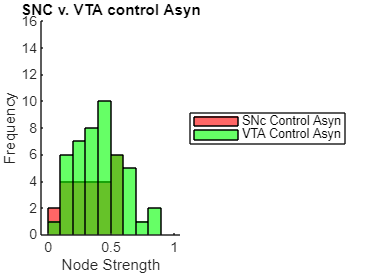

% 
% figure;
% histogram(group_snc_control_asyn ,edges, 'FaceColor', 'red');
% hold on;
% histogram(group_vta_control_asyn,edges, 'FaceColor', 'green');
% title('SNC v. VTA control Asyn');
% legend('SNc Control Asyn', 'VTA Control Asyn',  'Location', 'eastoutside');
% xlabel('Node Strength');
% ylabel('Frequency')
% ylim([0 16]);
% yticks(0:2:16);
% box off;
% saveas(gcf, fullfile(output_directory, 'Region SNC Conrol  v VTA control Asyn.svg'));

% 
% [h3,p3,ci3,stats3] = ttest2(group_snc_control_asyn, group_vta_control_asyn);
% disp('SNC v. VTA control Asyn:')

SNC v. VTA control Asyn:


% disp(['Test Statistic: ', num2str(stats3.tstat)]);

Test Statistic: -1.9707


% disp(['P-value: ', num2str(p3)]);

P-value: 0.052834


% disp('Confidence Interval:');

Confidence Interval:


% disp(ci3);

   -0.1839    0.0012



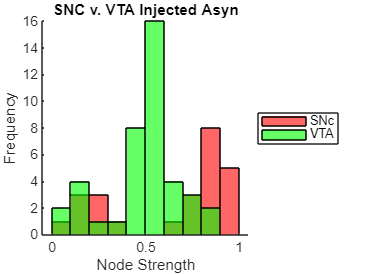

% 
% figure;
% histogram(group_snc_injected_asyn ,edges, 'FaceColor', 'red');
% hold on;
% histogram(group_vta_injected_asyn,edges, 'FaceColor', 'green');
% title('SNC v. VTA Injected Asyn');
% legend('SNc ', 'VTA ',  'Location', 'eastoutside');
% xlabel('Node Strength');
% ylabel('Frequency')
% ylim([0 16]);
% yticks(0:2:16);
% box off;
% saveas(gcf, fullfile(output_directory, 'Region SNC v. VTA Injected Asyn.svg'));

% 
% [h4,p4,ci4,stats4] = ttest2(group_snc_injected_asyn, group_vta_injected_asyn);
% disp('SNC v. VTA Injected Asyn:')

SNC v. VTA Injected Asyn:


% disp(['Test Statistic: ', num2str(stats4.tstat)]);

Test Statistic: 2.2307


% disp(['P-value: ', num2str(p4)]);

P-value: 0.029213


% disp('Confidence Interval:');

Confidence Interval:


% disp(ci4);

    0.0146    0.2657



mean_control_pff = mean([group_snc_control_pff,group_vta_control_pff])

mean_control_pff = 0.3849

mean_control_asyn = mean([group_snc_control_asyn, group_vta_control_asyn])

mean_control_asyn = 0.3749

mean_injected_pff = mean([group_snc_injected_pff, group_vta_injected_pff])

mean_injected_pff = 0.4760

mean_injected_asyn = mean([group_snc_injected_asyn,group_vta_injected_asyn])

mean_injected_asyn = 0.5329

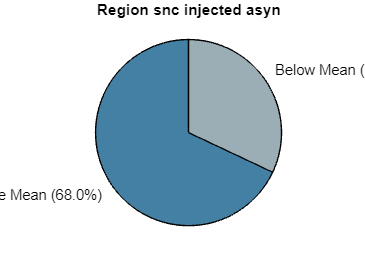

output_directory = 'F:\Data\Slice Video Processing\figure_outputs_matlab\graphs';
if ~exist(output_directory, 'dir')
    mkdir(output_directory);
end

% Find indices of elements above the median 
above_mean_snc_injected_asyn = find([group_snc_injected_asyn] > mean_injected_asyn);
below_mean_snc_injected_asyn = find([group_snc_injected_asyn] < mean_injected_asyn);

% Count the number of elements above and below the median
freq_above_mean_snc_injected_asyn = length(above_mean_snc_injected_asyn);
freq_below_mean_snc_injected_asyn = length(below_mean_snc_injected_asyn);

% Create a vector to hold the counts
counts5 = [freq_above_mean_snc_injected_asyn, freq_below_mean_snc_injected_asyn];

% Calculate percentages
total_count_snc_injected_asyn = sum(counts5);
percentages_snc_injected_asyn = (counts5 / total_count_snc_injected_asyn) * 100;

% Convert percentages to cell array of strings
percentages_str_snc_injected_asyn = cellstr(num2str(percentages_snc_injected_asyn', '%1.1f%%'));

% Combine labels and percentages for display
label_percentages_snc_injected_asyn = strcat(labels', {' ('}, percentages_str_snc_injected_asyn, {')'});

% Create the pie chart with specified colors and display percentages
figure;
pie(counts5, label_percentages_snc_injected_asyn);
colormap(colorB);
title('Region snc injected asyn');
saveas(gcf, fullfile(output_directory, 'Pie2_snc_injected_asyn_with_percentages.svg'));

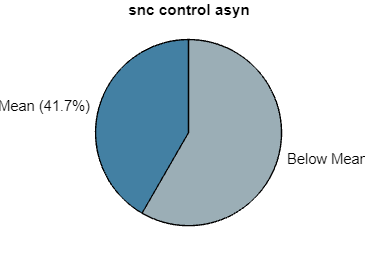

% Find indices of elements above the median 
abovemean_snc_control_asyn = find([group_snc_control_asyn] > mean_control_asyn);
belowmean_snc_control_asyn = find([group_snc_control_asyn] < mean_control_asyn);

% Count the number of elements above and below the median
freq_above_mean_snc_control_asyn = length(abovemean_snc_control_asyn);
freq_below_mean_snc_control_asyn = length(belowmean_snc_control_asyn);

% Create a vector to hold the counts
counts6 = [freq_above_mean_snc_control_asyn, freq_below_mean_snc_control_asyn];

% Calculate percentages
total_count_snc_control_asyn = sum(counts6);
percentages_snc_control_asyn = (counts6 / total_count_snc_control_asyn) * 100;

% Convert percentages to cell array of strings
percentages_str_snc_control_asyn = cellstr(num2str(percentages_snc_control_asyn', '%1.1f%%'));

% Combine labels and percentages for display
label_percentages_snc_control_asyn = strcat(labels', {' ('}, percentages_str_snc_control_asyn, {')'});

% Create the pie chart with specified colors and display percentages
figure;
pie(counts6, label_percentages_snc_control_asyn);
colormap(colorB);
title('snc control asyn');
saveas(gcf, fullfile(output_directory, 'Pie2_snc_control_asyn_with_percentages.svg'));

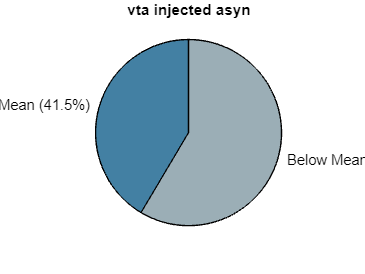


% Find indices of elements above the median 
above_mean_vta_injected_asyn = find([group_vta_injected_asyn] > mean_injected_asyn);
below_mean_vta_injected_asyn = find([group_vta_injected_asyn] < mean_injected_asyn);

% Count the number of elements above and below the median
freq_above_mean_vta_injected_asyn = length(above_mean_vta_injected_asyn);
freq_below_mean_vta_injected_asyn = length(below_mean_vta_injected_asyn);

% Create a vector to hold the counts
counts7 = [freq_above_mean_vta_injected_asyn, freq_below_mean_vta_injected_asyn];

% Calculate percentages
total_count_vta_injected_asyn = sum(counts7);
percentages_vta_injected_asyn = (counts7 / total_count_vta_injected_asyn) * 100;

% Convert percentages to cell array of strings
percentages_str_vta_injected_asyn = cellstr(num2str(percentages_vta_injected_asyn', '%1.1f%%'));

% Combine labels and percentages for display
label_percentages_vta_injected_asyn = strcat(labels', {' ('}, percentages_str_vta_injected_asyn, {')'});

% Create the pie chart with specified colors and display percentages
figure;
pie(counts7, label_percentages_vta_injected_asyn);
colormap(colorB);
title('vta injected asyn');
saveas(gcf, fullfile(output_directory, 'Pie2_vta_injected_asyn_with_percentages.svg'));

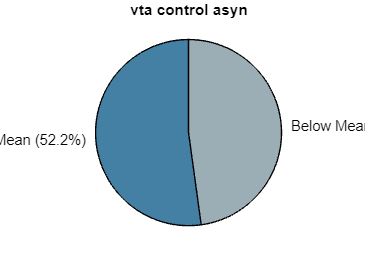


% Find indices of elements above the median 
abovemean_vta_control_asyn = find([group_vta_control_asyn] > mean_control_asyn);
belowmean_vta_control_asyn = find([group_vta_control_asyn] < mean_control_asyn);

% Count the number of elements above and below the median
freq_above_mean_vta_control_asyn = length(abovemean_vta_control_asyn);
freq_below_mean_vta_control_asyn = length(belowmean_vta_control_asyn);

% Create a vector to hold the counts
counts8 = [freq_above_mean_vta_control_asyn, freq_below_mean_vta_control_asyn];

% Calculate percentages
total_count_vta_control_asyn = sum(counts8);
percentages_vta_control_asyn = (counts8 / total_count_vta_control_asyn) * 100;

% Convert percentages to cell array of strings
percentages_str_vta_control_asyn = cellstr(num2str(percentages_vta_control_asyn', '%1.1f%%'));

% Combine labels and percentages for display
label_percentages_vta_control_asyn = strcat(labels', {' ('}, percentages_str_vta_control_asyn, {')'});

% Create the pie chart with specified colors and display percentages
figure;
pie(counts8, label_percentages_vta_control_asyn);
colormap(colorB);
title('vta control asyn');
saveas(gcf, fullfile(output_directory, 'Pie2_vta_control_asyn_with_percentages.svg'));

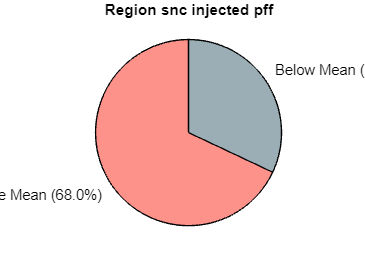

output_directory = 'F:\Data\Slice Video Processing\figure_outputs_matlab\graphs';
if ~exist(output_directory, 'dir')
    mkdir(output_directory);
end
% Find indices of elements above the median 
above_mean_snc_injected_pff = find([group_snc_injected_pff] > mean_injected_pff);
below_mean_snc_injected_pff = find([group_snc_injected_pff] < mean_injected_pff);

% Count the number of elements above and below the median
freq_above_mean_snc_injected_pff = length(above_mean_snc_injected_pff);
freq_below_mean_snc_injected_pff = length(below_mean_snc_injected_pff);

% Create a vector to hold the counts
counts5 = [freq_above_mean_snc_injected_pff, freq_below_mean_snc_injected_pff];

% Calculate percentages
total_count_snc_injected_pff = sum(counts5);
percentages_snc_injected_pff = (counts5 / total_count_snc_injected_pff) * 100;

% Convert percentages to cell array of strings
percentages_str_snc_injected_pff = cellstr(num2str(percentages_snc_injected_pff', '%1.1f%%'));

% Combine labels and percentages for display
label_percentages_snc_injected_pff = strcat(labels', {' ('}, percentages_str_snc_injected_pff, {')'});

% Create the pie chart with specified colors and display percentages
figure;
pie(counts5, label_percentages_snc_injected_pff);
colormap(colorB);
title('Region snc injected pff');
saveas(gcf, fullfile(output_directory, 'Pie2_snc_injected_pff_with_percentages.svg'));

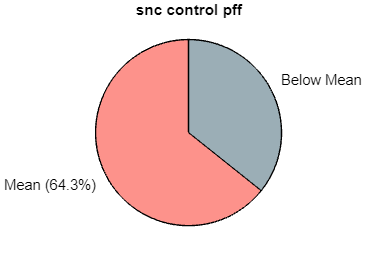


% Find indices of elements above the median 
abovemean_snc_control_pff = find([group_snc_control_pff] > mean_control_pff);
belowmean_snc_control_pff = find([group_snc_control_pff] < mean_control_pff);

% Count the number of elements above and below the median
freq_above_mean_snc_control_pff = length(abovemean_snc_control_pff);
freq_below_mean_snc_control_pff = length(belowmean_snc_control_pff);

% Create a vector to hold the counts
counts6 = [freq_above_mean_snc_control_pff, freq_below_mean_snc_control_pff];

% Calculate percentages
total_count_snc_control_pff = sum(counts6);
percentages_snc_control_pff = (counts6 / total_count_snc_control_pff) * 100;

% Convert percentages to cell array of strings
percentages_str_snc_control_pff = cellstr(num2str(percentages_snc_control_pff', '%1.1f%%'));

% Combine labels and percentages for display
label_percentages_snc_control_pff = strcat(labels', {' ('}, percentages_str_snc_control_pff, {')'});

% Create the pie chart with specified colors and display percentages
figure;
pie(counts6, label_percentages_snc_control_pff);
colormap(colorB);
title('snc control pff');
saveas(gcf, fullfile(output_directory, 'Pie2_snc_control_pff_with_percentages.svg'));

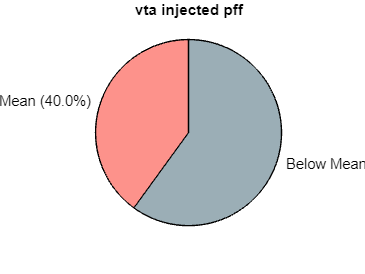


% Find indices of elements above the median 
above_mean_vta_injected_pff = find([group_vta_injected_pff] > mean_injected_pff);
below_mean_vta_injected_pff = find([group_vta_injected_pff] < mean_injected_pff);

% Count the number of elements above and below the median
freq_above_mean_vta_injected_pff = length(above_mean_vta_injected_pff);
freq_below_mean_vta_injected_pff = length(below_mean_vta_injected_pff);

% Create a vector to hold the counts
counts7 = [freq_above_mean_vta_injected_pff, freq_below_mean_vta_injected_pff];

% Calculate percentages
total_count_vta_injected_pff = sum(counts7);
percentages_vta_injected_pff = (counts7 / total_count_vta_injected_pff) * 100;

% Convert percentages to cell array of strings
percentages_str_vta_injected_pff = cellstr(num2str(percentages_vta_injected_pff', '%1.1f%%'));

% Combine labels and percentages for display
label_percentages_vta_injected_pff = strcat(labels', {' ('}, percentages_str_vta_injected_pff, {')'});

% Create the pie chart with specified colors and display percentages
figure;
pie(counts7, label_percentages_vta_injected_pff);
colormap(colorB);
title('vta injected pff');
saveas(gcf, fullfile(output_directory, 'Pie2_vta_injected_pff_with_percentages.svg'));

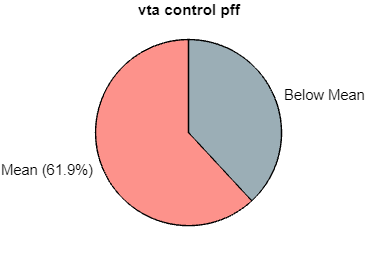


% Find indices of elements above the median 
abovemean_vta_control_pff = find([group_vta_control_pff] > mean_control_pff);
belowmean_vta_control_pff = find([group_vta_control_pff] < mean_control_pff);

% Count the number of elements above and below the median
freq_above_mean_vta_control_pff = length(abovemean_vta_control_pff);
freq_below_mean_vta_control_pff = length(belowmean_vta_control_pff);

% Create a vector to hold the counts
counts8 = [freq_above_mean_vta_control_pff, freq_below_mean_vta_control_pff];

% Calculate percentages
total_count_vta_control_pff = sum(counts8);
percentages_vta_control_pff = (counts8 / total_count_vta_control_pff) * 100;

% Convert percentages to cell array of strings
percentages_str_vta_control_pff = cellstr(num2str(percentages_vta_control_pff', '%1.1f%%'));

% Combine labels and percentages for display
label_percentages_vta_control_pff = strcat(labels', {' ('}, percentages_str_vta_control_pff, {')'});

% Create the pie chart with specified colors and display percentages
figure;
pie(counts8, label_percentages_vta_control_pff);
colormap(colorB);
title('vta control pff');
saveas(gcf, fullfile(output_directory, 'Pie2_vta_control_pff_with_percentages.svg'));

function node_group = groupNodeStrength(tbl)
    node_group = [];
    for i = 1:height(tbl)
        test = tbl.nodeDegree_norm{i};
        node_group = [node_group, test];
    end
end

function [assortavityAll] = extractassortavity(tbl)
    assortavityAll = [];
    for i = 1:height(tbl)
        currentassortavity = cell2mat(tbl.assortavity(i));
        assortavityAll = vertcat(assortavityAll,currentassortavity);
    end
end

function [modularityQAll] = extractmodularityQ(tbl)
    modularityQAll = [];
    for i = 1:height(tbl)
        currentmodularityQ = cell2mat(tbl.modularityQ(i));
        modularityQAll = vertcat(modularityQAll,currentmodularityQ);
    end
end

function [ccAll] = extractCC(tbl)
    ccAll = [];
    for i = 1:height(tbl)
        currentCC = cell2mat(tbl.clusterCoef_mean(i));
        ccAll = vertcat(ccAll, currentCC);
    end
end

function [densityAll] = extractdensity(tbl)
    densityAll = [];
    for i = 1:height(tbl)
        currentdensity = cell2mat(tbl.density(i));
        densityAll = vertcat(densityAll, currentdensity);
    end
end